### Nombre completo: Josef Ruzicka   

### Carnet: B87095

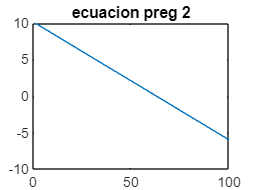

% Codigo ejecutable

% Motivación: Profe ayúdeme, le prometo que voy a ponerle bastante más, es
% que he estado tallado con el proyecto de grad y el trabajo.
% PD: El curso me encanta.

% PARTE DESARROLLO
% 2)
% Visualizamos funcion.
a = (-1)^4 - 8*(-1)^3 +1;
b = (1)^4 - 8*(1)^3 +1;
vector = linspace(a, b);
plot(vector)
title('ecuacion preg 2')

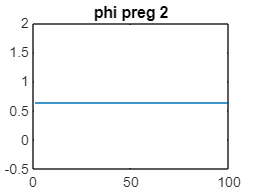


% visualizamos phi propuesto
phi_a = nthroot( (1+(-1)^4) , 3)/2;
phi_b = nthroot( (1+(1)^4) , 3)/2;
vector = linspace(phi_a, phi_b);
plot(vector)
title('phi preg 2')

% PARTE PROGRAMADA
% 1)
disp('PREGUNTA 1 PROGRAMADA')

PREGUNTA 1 PROGRAMADA


% Tomamos F y despejamos x para obtener phi.
% f = @(x) x^4 - 8*x^3 + 1;
% Ahora utilizando la sucesión dada en parte 1.
phi = @(x) nthroot( (1+x^4) , 3)/2;
% punto inicial
x0 = 1;
tol = 1e-3;
itermax = 14; % Basado en experiencia: similar a cantidad de iters que hemos utilizado en clase
[x, k, T] = PuntoFijo(phi, x0, tol, itermax)

x = 0.5111

k = 5

T = 6×4 table
    k       x        g(x)         err    
    _    _______    _______    __________

    0          1    0.62996       0.37004
    1    0.62996    0.52498        0.5874
    2    0.52498    0.51235       0.19997
    3    0.51235    0.51123      0.024647
    4    0.51123    0.51113     0.0021933
    5    0.51113    0.51113    0.00018757



% ------------------------------
% 2)

disp('PREGUNTA 2 PROGRAMADA')

PREGUNTA 2 PROGRAMADA


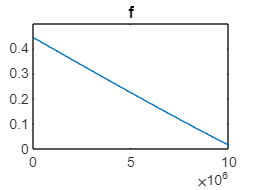

% Intentamos bisección
g = 9.8;
v0 = 10;
y = 1; 
a = 0; % Alcance minimo
b = sqrt( (2*g*y)/v0^2 ); % alcance maximo
f = @(x2) sqrt( (2*g*y)/v0^2 ) - sin(x2);

% Al plotear la función observamos que no sé cumple el cambio de signo que
% el teorema del valor intermedio nos proporcionaría.
% Esto tiene sentido porque no esperariamos que el proyectil se disparara en la dirección opuesta.
vector = linspace(0, b, 10000000);
plot(f(vector))
title('f')

% con c = theta y misma tol anterior
%[c, iters, T] = Biseccion(f, a, b, tol)

% Si intentmos con Newton-Rhapson
% Derivamos f. df = 0 - cos(theta)
df = @(x3) -1*cos(x3);
% usamos a como x0
[x, k, T] = NewRaph(f, df, a, tol, itermax)

x = 0.4586

k = 2

T = 3×5 table
    k      x0          x          f(x)          err    
    _    _______    _______    __________    __________

    0          0    0.44272      0.014321             1
    1    0.44272    0.45857    5.4404e-05      0.034562
    2    0.45857    0.45863    8.1478e-10    0.00013229



% Comparamos con matlab
matlab_ans = fzero(f, a)

matlab_ans = 0.4586


error_relativo = abs(matlab_ans - x)/abs(matlab_ans)

error_relativo = 1.9813e-09


% --------------------------------
% 3) ver funciones.

disp('PREGUNTA 3 PROGRAMADA')

PREGUNTA 3 PROGRAMADA


ans = cambiarBase(28, 5)

new_n = 28

index = 1

ans =      1     0     3


% prueba de manejo de error
ans = cambiarBase(28, -5)

b debe ser mayor a 0


ans = 'error'

# Funciones

function [ans] = cambiarBase(n, b) % PARTE PROGRAMADA 3.
    if b > 0
        new_n = n
        residuals = [];
        index = 1
        while new_n > 0
            residuals(index) = mod(new_n, b);
            new_n = floor(new_n/b);
            index = index+1;
        end
        % flippeamos residuals.
        fliplr(residuals);
    else
        disp('b debe ser mayor a 0');
        ans = 'error'; % para que nos alga error feo
        return
    end
end
% -------------------------------------------------

function [c, iters, T] = Biseccion(f, a, b, tol)
if f(a)*f(b) > 0
    disp('No se cumple el cambio de signo')
    return
end

iters = floor(log2((b-a)/tol)) + 1;

T(1,:) = zeros(1,6); % Defino la primer fila de la tabla

for k = 1:iters+1
    c = (a+b)/2;
    T(k,:) = [k-1, a, c, b, f(c) b-a]; % Se van creando las filas siguientes

    if f(c) == 0
        a = c;
        b = c;
    elseif f(a)*f(c) < 0
        b = c;
    else
        a = c;
    end

end

T = array2table(T, "VariableNames",{'k', 'a', 'c', 'b', 'f(c)', 'error'});

end

% +++

function [x, k, T] = NewRaph(f, df, x0, tol, iterMax)
k = 0;
x = x0;
err = tol+1;
T = zeros(1,5);

while k < iterMax && err >= tol
    q = df(x);
    if q==0
        disp('Se anula la derivada')
        return
    end

    x = x-f(x)/q;
    err = abs(x-x0)/abs(x);
    T(k+1,:) = [k x0 x f(x) err];
    x0 = x;
    k = k+1;

end
T = array2table(T, 'VariableNames',{'k', 'x0', 'x','f(x)', 'err'});
k = k-1; % Ajustamos el k

end

% +++

function [x, k, T] = Secante(f, x0, x1, tol, iterMax)
k = 0;
err = tol+1;
T(1,:) = [0 x0  x1 f(x1) abs(x0-x1)/abs(x1)];

while k < iterMax && err >= tol
    q = f(x1) - f(x0);
    if q==0
        disp('Pendiente indefinida')
    end

    t = x1;
    x1 = x1-f(x1)*(x1-x0)/q;
    err = abs(x0-x1)/abs(x1);
    x0 = t;
    k = k+1;
    T(k+1,:) = [k x0  x1 f(x1) err];
end

x = x1;
T = array2table(T, 'VariableNames',{'k', 'x0', 'x1', 'f(x1)', 'err'});
end


% +++

function [x, k, T] = PuntoFijo(f, x0, tol, iterMax)
k = 0;
x = x0;
err = tol+1; 
T(1,:) = [k x f(x) abs(x-f(x))];

while (k < iterMax) && (err > tol)
    x = f(x);
    err = abs(x-x0)/abs(x); % error relativo 
    x0 = x;
    k = k+1;
    T(k+1,:) = [k x f(x) err];
end

T = array2table(T, 'VariableNames',{'k', 'x', 'g(x)', 'err'});
end
